### Plots & Diagrams

clear;
neatov2.connect()

Deleting previous Neato connection.
Connecting to the Neato.


ans =   neatov2 with no properties.


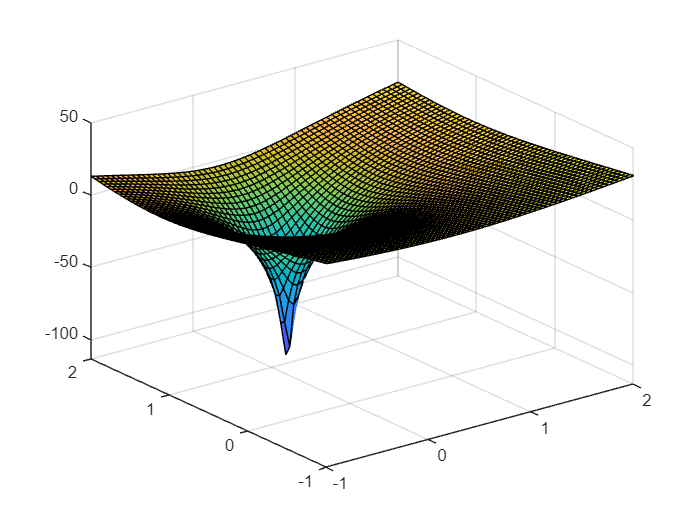


[x,y]=meshgrid(-1:0.05:2,-1:0.05:2); % define the potential at all mesh points

v = 30*log(sqrt((x-0.244).^2+(y-1.128).^2)); % function that defines Bob as sink

surf(x,y,v)

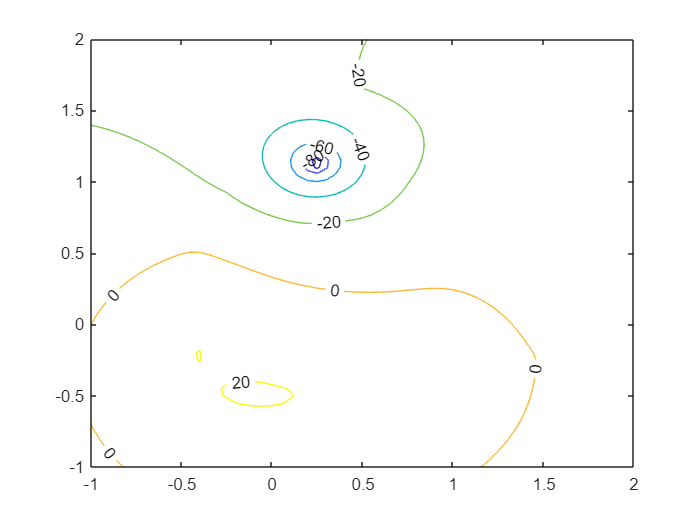


load("global_points.mat")
global_points = global_points; % global points from gauntlet map

i = 1;
while i < length(global_points) + 1 % loop through all global points
    % define x, y coordinate pair
    x_coord = global_points(1,i);
    y_coord = global_points(2,i);
    v = build_equation(v, x, y, x_coord, y_coord); % add source at coordinate
    i = i + 1;
end

% plot contours with levels marked
figure();
contour(x,y,v,'ShowText','On')


neatov2.setFlatlandContours(x,y,v);

% plot surface
% figure();
% surf(x, y, v)

% Vector Field
% figure();
% U = sin(y);
% V = cos(x);
% quiver(x, y, U, V)

### Gradient Set-up

syms x y

% flatlands
f = 100*log(sqrt((x-0.244).^2+(y-1.128).^2));

load("global_points.mat")
global_points = global_points; % global points from gauntlet map

i = 1;
while i < length(global_points) + 1 % loop through all global points
    % define x, y coordinate pair
    x_coord = global_points(1,i);
    y_coord = global_points(2,i);
    f = build_equation(f, x, y, x_coord, y_coord); % add source at coordinate
    i = i + 1;
end

fx = diff(f,x);
fy = diff(f,y);
gradient = [fx, fy];

### Implementation: Run Neato

grad =   -25.0371
  -85.3060


ans = 88.9043

newOrientation = 1.2853

distance = 0.0316

r =     0.0089
    0.0303


grad =   -25.2653
  -87.6669


ans = 91.2349

newOrientation = 1.2902

distance = 0.0333

r =     0.0181
    0.0623


grad =   -25.4749
  -90.2642


ans = 93.7902

newOrientation = 1.2957

distance = 0.0352

r =     0.0277
    0.0962


grad =   -25.6775
  -93.1440


ans = 96.6185

newOrientation = 1.3018

distance = 0.0373

r =     0.0376
    0.1322


grad =   -25.8890
  -96.3687


ans = 99.7856

newOrientation = 1.3083

distance = 0.0398

r =     0.0479
    0.1707


grad =   -26.1319
 -100.0252


ans = 103.3823

newOrientation = 1.3153

distance = 0.0428

r =     0.0587
    0.2120


grad =   -26.4385
 -104.2388


ans = 107.5394

newOrientation = 1.3224

distance = 0.0463

r =     0.0701
    0.2569


grad =   -26.8572
 -109.1977


ans = 112.4520

newOrientation = 1.3296

distance = 0.0506

r =     0.0822
    0.3060


grad =   -27.4630
 -115.1993


ans = 118.4276

newOrientation = 1.3368

distance = 0.0561

r =     0.0952
    0.3605


grad =   -28.3790
 -122.7501


ans = 125.9879

newOrientation = 1.3436

distance = 0.0635

r =     0.1095
    0.4224


grad =   -29.8153
 -132.8039


ans = 136.1096

newOrientation = 1.3500

distance = 0.0741

r =     0.1257
    0.4947


grad =   -32.1202
 -147.4309


ans = 150.8893

newOrientation = 1.3563

distance = 0.0911

r =     0.1451
    0.5837


grad =   -35.8353
 -172.1536


ans = 175.8438

newOrientation = 1.3656

distance = 0.1237

r =     0.1703
    0.7048


grad =   -36.6033
 -238.0060


ans = 240.8042

newOrientation = 1.4182

distance = 0.2319

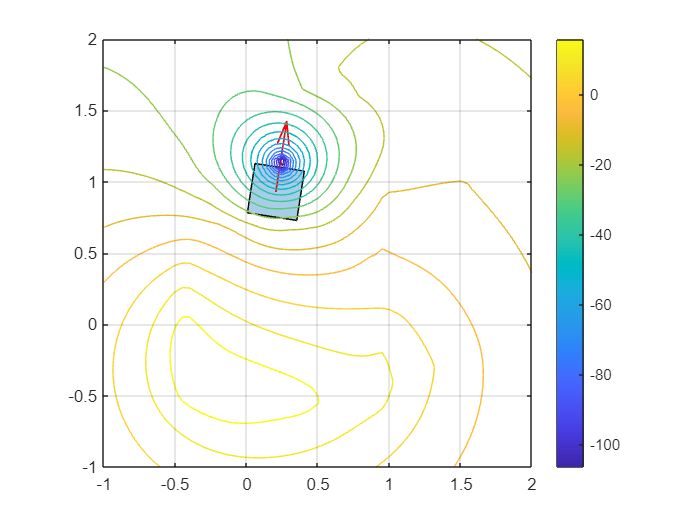

r =     0.2056
    0.9340


%Starting position and orientation
startingx = 0;
startingy = 0;
startingTheta = 0;

%Parameters
%lambda = 0.0000000005;
linearWheelV = 0.3;

%While loop parameters
i = 2;
i_max = 16;

%Initial position and gradient
r_0 = [startingx; startingy]; %First coordinate
r_list(:,1) = r_0;
r = r_0;

grad = double(subs(gradient, {x, y}, {r(1), r(2)}));
neatov2.setPositionAndOrientation(startingx,startingy,startingTheta)

%%FOR NON-SIMULATED%%
%orientation = startingTheta

while i < i_max && norm(grad) > 0.5
    grad = (double(subs(gradient, {x, y}, {r(1), r(2)})))'
    % CHANGE FOR #6: make lambda proportional to the gradiant
    norm(grad)
    lambda = 0.000005*norm(grad); % default lambda
    if norm(grad) > 4 % adjust lambda for extra steep steps
        lambda = 0.000004*norm(grad);
    end
    next_r = r - lambda*grad;
    vectorDiff = next_r-r;
    newOrientation = atan2(vectorDiff(2),vectorDiff(1))

    %%FOR NON-SIMULATED%%
    %deltaTheta = newOrientation-orientation;
    %angularV = -0.1/0.254;
    %spinTime = abs(deltaTheta/angularV);
    %neatov2.driveFor(spinTime, sign(deltaTheta)*-0.05, sign(deltaTheta)*0.05, true);
    %pause(.01)

    distance = norm(vectorDiff)
    % CHANGE FOR #6: if distance of path is insignificant, end the loop
    if distance < 0.0018
        break
    end
    driveTime = distance/linearWheelV;
    neatov2.setPositionAndOrientation(r(1),r(2),newOrientation)
    neatov2.driveFor(driveTime, linearWheelV, linearWheelV, true)

    %%FOR NON-SIMULATED%%
    %pause(.01)

    r = next_r
    r_list(:,i) = r(1,:);
    i = i + 1;

    %%FOR NON-SIMULATED%%
    %orientation = newOrientation; 
end

### Helper Functions

function [v] = build_equation(v, x, y, x_coord, y_coord)
% Add new source to equation evaluted at meshgrid.
%
% Inputs
%   v (square matrix): Equation evaluted at meshgrid
%   x (square matrix): X coordinates of meshgrid
%   y (square matric): Y coordinates of meshgrid
%   x_coord (float): X coordinate of source
%   y_coord(float): Y coordinate of source
%
% Returns
%   v (square matrix): Newly built equation evaluted at meshgrid

    v = v - 0.05 * (log(sqrt((x-x_coord).^2+(y-y_coord).^2)));
end